8.4 （太阳黑子）实时脚本

由张志涌编写、修改于 2023.1。

load sunspot.dat
t = sunspot(:,1)';
wolfer = sunspot(:,2)';
n = length(wolfer);

黑子指数拟合

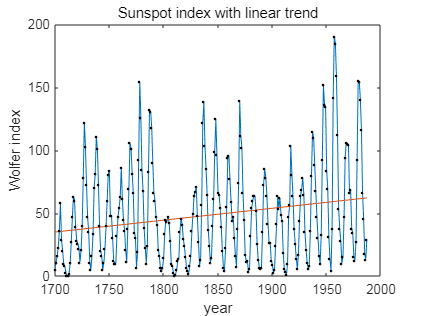

c = polyfit(t,wolfer,1);
trend = polyval(c,t);
plot(t,[wolfer; trend],'-',t,wolfer,'k.')
xlabel('year')
ylabel('Wolfer index')
title('Sunspot index with linear trend')

周期图

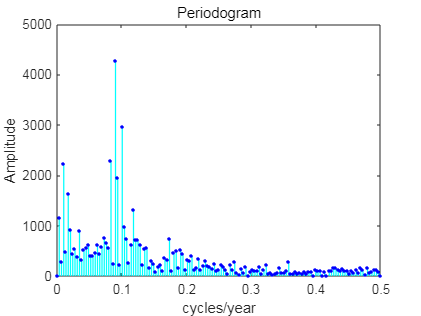

y = wolfer - trend;
Y = fft(y);
Fs = 1; 						% Sample rate
f = (0:n/2)*Fs/n;
pow = abs(Y(1:n/2+1));		%abs对数组每个元素求绝对值
pmax = 5000;
plot([f; f],[0*pow; pow],'c-', f,pow,'b.', ...
'linewidth',1,'markersize',8)
axis([0 .5 0 pmax])
xlabel('cycles/year')
ylabel('Amplitude')
title('Periodogram')

周期图细节

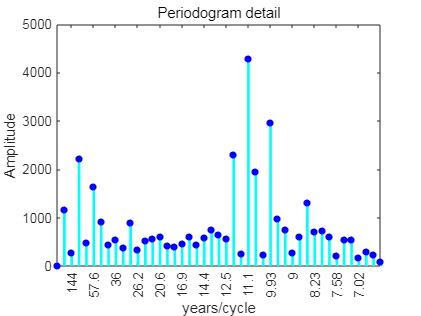

k = 0:44;
f = k/n;
pow = pow(k+1);
plot([f; f],[0*pow; pow],'c-',f,pow,'b.', ...
'linewidth',2,'markersize',16)
axis([0 max(f) 0 pmax])
k = 2:3:41;
f = k/n;
period = 1./f;				% 1被行数组f除
periods = num2str(period',3);
xticks(f)
xticklabels(periods)
xtickangle(90)
xlabel('years/cycle')
ylabel(' Amplitude ')
title('Periodogram detail')